clear all; close all;

% Figure settings 
% ------------------------------
f_xpos = 100; f_ypos = 500; f_width = 900; f_height = 500;
fig_pos	= [f_xpos f_ypos f_width f_height]; fig_color = 'white';
% ------------------------------

load('resampdataset.mat')
%Sampling-time is 1/15min, meaning that time-axis is in minutes
oneday = 60*60*24; %one day in minutes
n = 2; % How many days do we wants to see?
% figure(1)
% subplot(2,1,1)
% plot(time,q_u1)
% xlim([0 n*oneday])
% subplot(2,1,2)
figure(1)
plot(time*60,q_u2)
xlim([0 2*oneday])
title('Consumption Pattern')
xlabel('Time [sec]')
ylabel('Consumption over 2 days')


%Consumption Patteren
% f = fullfile('D:\GitRepose\AAU 7. semester\CA7_Writings\CA7_Writings_Worksheets\Pictures','ConsumptionPattern.pdf');
% exportgraphics(figure(1), f)
% , 'Resolution', 400

## FFT

y11 = fft(q_u2);
P22 = abs(y11/length(q_u2));
P11 = P22(1:length(q_u2)/2+1);
P11(2:end-1) = 2*P11(2:end-1);

P22a = angle(y11/length(q_u2));
P11a = P22a(1:length(q_u2)/2+1);
P11a(2:end-1) = 2*P11a(2:end-1);

%Time-axis
f = 1/(15*60)*(0:(length(q_u1)/2))/length(q_u1);
%Subplots with FFT of q_u1 & q_u2
figure(2)
subplot(2,1,1) 
plot(f,P11)
title('FFT of Consumption Pattern')
xlabel('Frequency [Hz]')
ylabel('Amplitude')
xlim([0 max(f)])
subplot(2,1,2)
plot(f,P11a)
title('Phase Shift of Harmonics Components')
xlabel('Frequency [Hz]')
ylabel('Phase shift [Rad]')
xlim([0 max(f)])


%FFT 
% f = fullfile('D:\GitRepose\AAU 7. semester\CA7_Writings\CA7_Writings_Worksheets\Pictures','FFT.pdf');
% exportgraphics(figure(2), f)


## Create waves and shit

% Periode of harmonics in min:
% T1 = 1/(1.15495*10^-5 * 60); 
% T2 = 1/(2.30989*10^-5 * 60);
% T3 = 1/(3.46484*10^-5 * 60);
% T4 = 1/(4.63291*10^-5 * 60);
% 
T1 = 1/(1.15495*10^-5); 
T2 = 1/(2.30989*10^-5);
T3 = 1/(3.46484*10^-5);
T4 = 1/(4.63291*10^-5);
T5 = 1/(f(77));


%Identify DC + 4 harmonic components:
K = 5.4274;
h1 = 2.84716;
h2 = 1.2767;
h3 = 0.411351;
h4 = 0.428664;
h5 = P11(77); % 77 giver den "pukkel" lige før h1 peaket.
tot = K + h1+h2+h3+h4+h5;

%Phaseshift of the harmonics:
% for ii = 1:length(P11a)
%    if P11(ii) > 0.261
%        ii
%    end
% end

%Phase shift at chosen harmonic components.
ph1 = P11a(89)

ph1 = -5.2790

ph2 = P11a(177)

ph2 = -5.0431

ph3 = P11a(265)

ph3 = 5.2835

ph4 = P11a(354)

ph4 = -2.0002

ph5 = P11a(77)

ph5 = 5.2314


% theta1 = ph1*2*pi*1/(T1/60);
% theta2 = ph2*2*pi*1/(T2/60);
% theta3 = ph3*2*pi*1/(T3/60);
% theta4 = ph4*2*pi*1/(T4/60);

test = 31500-8825; % den tid vi flytter toppen, for at passe med datasettets top

theta1 = test*(-2*pi*1/(T1));
theta2 = test*(-2*pi*1/(T2));
theta3 = test*(-2*pi*1/(T3));
theta4 = test*(-2*pi*1/(T4));
theta5 = test*(-2*pi*1/(T5));

t = 0:1:60*60*48;
% (K+firsth+sech+thirdh+fourthh)/tot;
w1 = h1/tot * sin(2*pi*1/T1 * t + ph1+theta1);
w2 = h2/tot * sin(2*pi*1/T2 * t + ph2+theta2);
w3 = h3/tot * sin(2*pi*1/T3 * t + ph3+theta3);
w4 = h4/tot * sin(2*pi*1/T4 * t + ph4+theta4);
% w5 = h5/tot * sin(2*pi*1/T5 * t + ph5+theta5);
% w1 = h1/tot * sin(2*pi*1/T1 * t + ph1);
% w2 = h2/tot * sin(2*pi*1/T2 * t + ph2);
% w3 = h3/tot * sin(2*pi*1/T3 * t + ph3);
% w4 = h4/tot * sin(2*pi*1/T4 * t + ph4);
% w5 = h5/tot * sin(2*pi*1/T5 * t + ph5);

ConsumerPattern = (K/tot)+w1+w2+w3+w4;
% figure()
% plot(t,ConsumerPattern)
% xlim([0 2*24*60])

## Comparisson of data set and harmonic (DC + 4)


figure(3)
plot(time*60,q_u2/max(q_u2))
hold on
plot(t,ConsumerPattern)
hold off
xlim([0 60*60*48])
title('Comparisson of Real Data and Estimate')
legend('Consumption pattern','Consumption estimation','FontSize',16)
xlabel('Time [sec]')
ylabel('Normalised consumption')
ylim([0 1.05])

ax = gca;
ax.FontSize = 22;




%Comparisson
% f = fullfile('D:\GitRepose\AAU 7. semester\CA7_Writings\CA7_Writings_Worksheets\Pictures','Comparisson.pdf')
% exportgraphics(figure(3), f)

## Y = C*x

% clear t; 
% w1 =@(t) h1/tot * cos(2*pi*1/T1 * t + theta*2*pi*1/(T1/60)-pi/2);
% w2 =@(t) h2/tot * cos(2*pi*1/T2 * t + theta*2*pi*1/(T2/60)-pi/2);
% w3 =@(t) h3/tot * cos(2*pi*1/T3 * t + theta*2*pi*1/(T3/60)-pi/2);
% w4 =@(t) h4/tot * cos(2*pi*1/T4 * t + theta*2*pi*1/(T4/60)-pi/2);
% 
% c = [1 1 0 1 0 1 0 1 0];
% x =@(t) [K/tot w1(t) 0 w2(t) 0 w3(t) 0 w4(t) 0]';
% 
% for t=1:1:60*48
%     y(t) = c*x(t);
% end

## Comparisson of the Harminic model and ss model

% figure()
% plot(ConsumerPattern)
% hold on 
% plot(y,'--')
% hold off

## Comparisson of data set and harmonic (DC + 4) (Poster version=

f = figure(3); f.Position = fig_pos; f.Color = fig_color;
figures = f;

plot(time*60,q_u2/max(q_u2))
hold on
plot(t,ConsumerPattern)
hold off
xlim([0 60*60*48])
title('Comparisson of Real Data and Estimate')
legend('Consumption pattern','Consumption estimation','FontSize',16)
xlabel('Time [sec]')
ylabel('Normalised consumption')
ylim([0 1.05])

ax = gca;
ax.FontSize = 22;

## Export figures

% Just change savepath to whichever fits you!
savepath = '/Users/martin/Documents/Git/Repos/CA7_Writings/CA7_Writings_SciPaper/Poster/Figures'

savepath = '/Users/martin/Documents/Git/Repos/CA7_Writings/CA7_Writings_SciPaper/Poster/Figures'

filename = ["Kalman_Poster.pdf"]

filename = "Kalman_Poster.pdf"

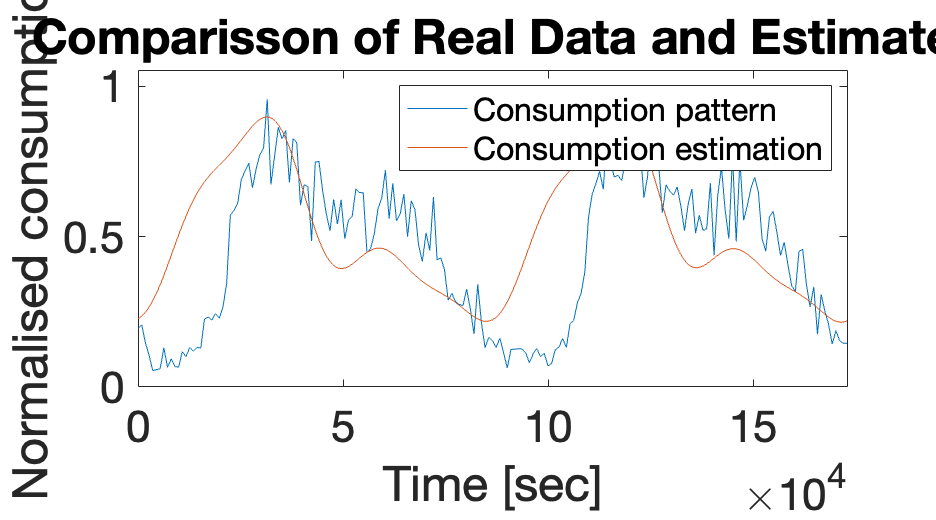

f = "/Users/martin/Documents/Git/Repos/CA7_Writings/CA7_Writings_SciPaper/Poster/Figures/Kalman_Poster.pdf"

for i=1:length(figures)
    f = fullfile(savepath, append(filename(i)))

    exportgraphics(figures(i), f,'Resolution', 10) % Resolution doesn't
	% if export filetype is png
end